# Boundary Analysis

clear;
clc;

## Wild Type

WT = "/Users/Priya/testoutput/TestMammaryMonolayerWT/results_from_time_0/heterotypicboundary.dat";
heterotypicboundaryWTall = importfile_heterotypicboundaryall(WT);

## B1 ME KO

B1MEKO = "/Users/Priya/testoutput/TestMammaryMonolayerB1MEKO/results_from_time_0/heterotypicboundary.dat";
heterotypicboundaryB1MEKOall = importfile_heterotypicboundaryall(B1MEKO);

## ME KO

MEKO = "/Users/Priya/testoutput/TestMammaryMonolayerMEKO/results_from_time_0/heterotypicboundary.dat";
heterotypicboundaryMEKOall = importfile_heterotypicboundaryall(MEKO);

## Plot Time vs Heterotypic Boundary Length

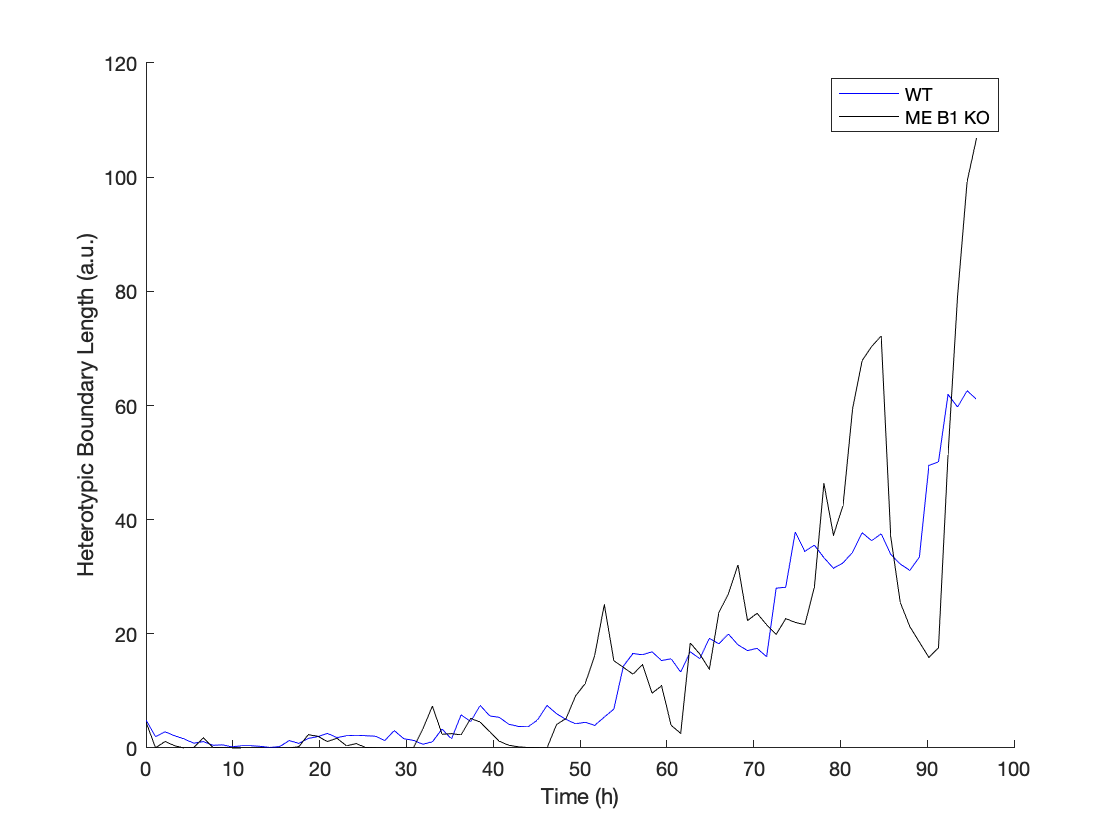

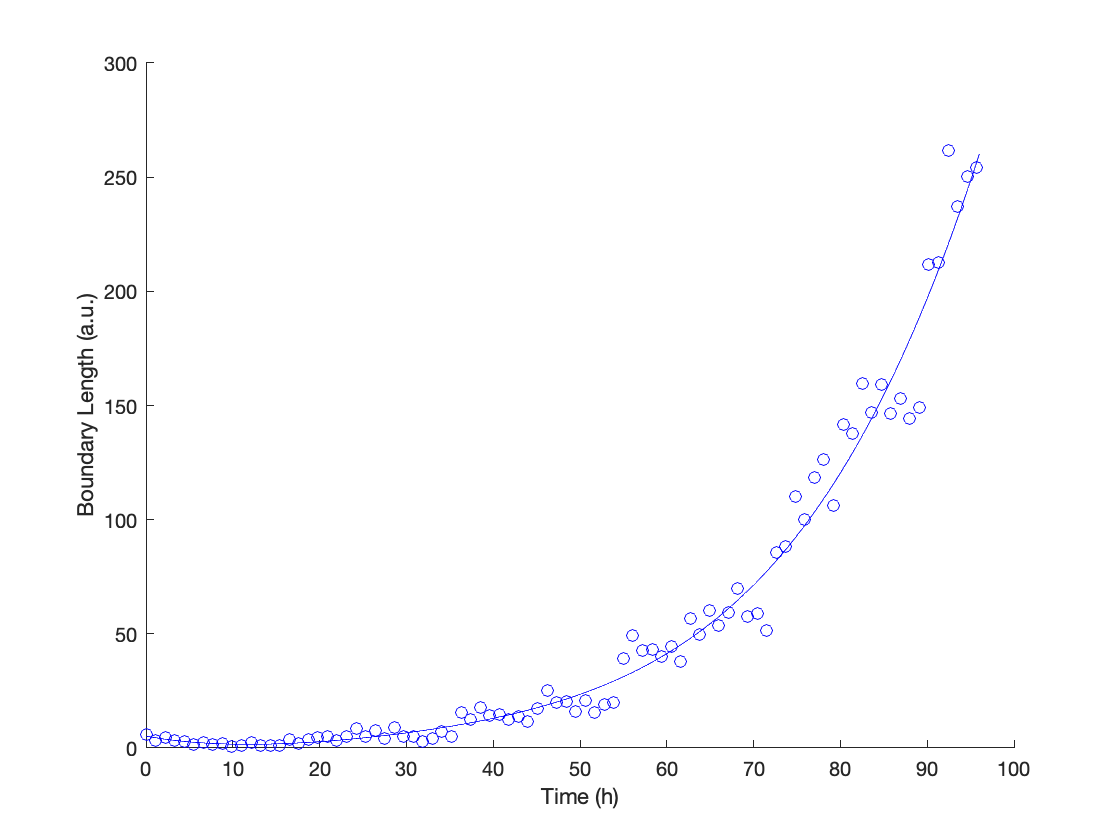

x=table2array(heterotypicboundaryWTall(:,1));

yWT=table2array(heterotypicboundaryWTall(:,2));

yB1MEK0=table2array(heterotypicboundaryB1MEKOall(:,2));

yMEKO=table2array(heterotypicboundaryMEKOall(:,2));

figure
hold on

plot(x(1:11:960), yWT(1:11:960), 'blue')

plot(x(1:11:960), yB1MEK0(1:11:960), 'black')

%plot(x, yMEKO)

hold off

ylabel ('Heterotypic Boundary Length (a.u.)')
xlabel('Time (h)')
legend({'WT', 'ME B1 KO'})

## Wild Type

WT = "/Users/Priya/testoutput/TestMammaryMonolayerWT/results_from_time_0/heterotypicboundary.dat";
heterotypicboundaryWT = importfile_heterotypicboundary(WT);

## B1 ME KO

B1MEKO = "/Users/Priya/testoutput/TestMammaryMonolayerB1MEKO/results_from_time_0/heterotypicboundary.dat";
heterotypicboundaryB1MEKO = importfile_heterotypicboundary(B1MEKO);

## ME KO

MEKO = "/Users/Priya/testoutput/TestMammaryMonolayerMEKO/results_from_time_0/heterotypicboundary.dat";
heterotypicboundaryMEKO = importfile_heterotypicboundary(MEKO);

## Plot Data

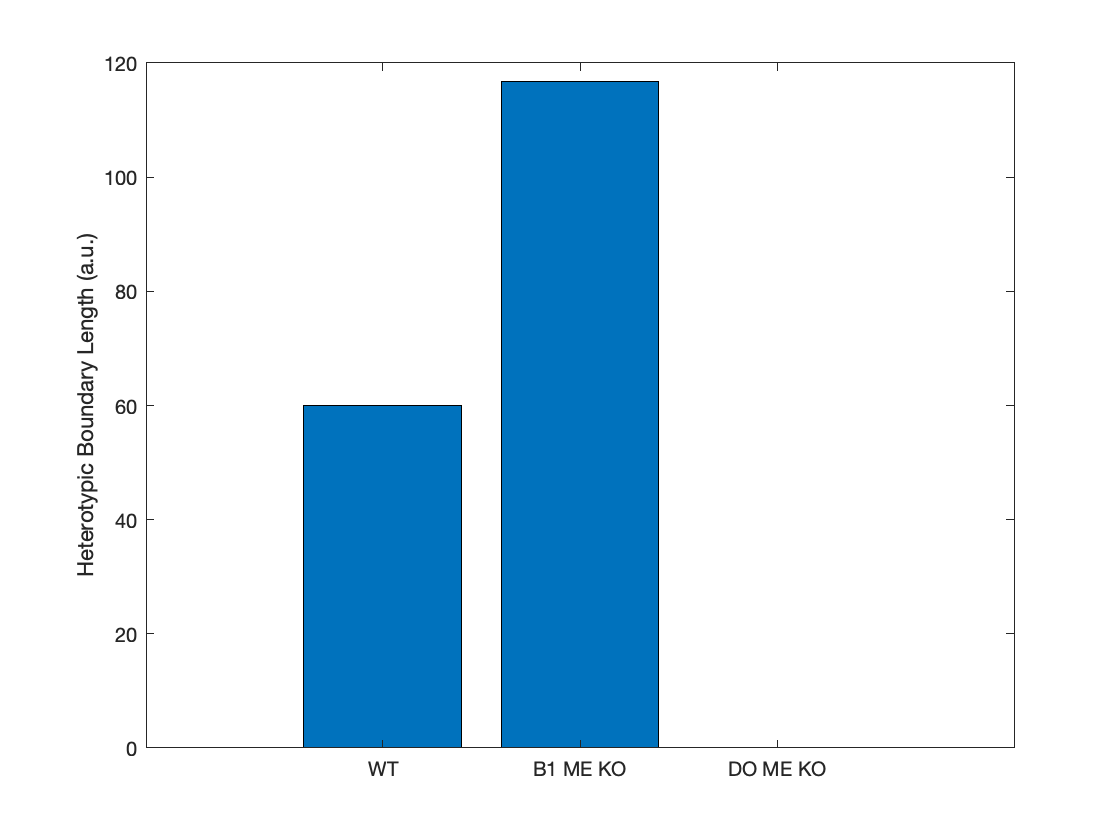

combined_table = table2array([heterotypicboundaryWT; heterotypicboundaryB1MEKO; heterotypicboundaryMEKO]);

figure

bar(combined_table(:,2))
set(gca, 'xtick', [1,2,3], 'xticklabel', {'WT', 'B1 ME KO', 'DO ME KO'})
ylabel ('Heterotypic Boundary Length (a.u.)')